# Mode (de)Multiplexer with 2.5D varFDFD Solver

A **photonic mode multiplexer (MUX)** routes several independent input signals into distinct spatial modes of a multimode waveguide. Instead of relying on wavelength- or polarization-division multiplexing, a mode MUX increases channel capacity by mapping each single-mode input into a specific higher-order eigenmode (e.g., TE10, TM02, ...) of a wider bus waveguide. Because these modes are orthogonal, they can co-propagate within the same structure with minimal interference. Photonic MUX devices are widely used in on-chip mode-division multiplexing, high-speed optical interconnects, and mode-selective fiber–chip interfaces.

Typically, the physical footprint of a photonic MUX spans tens or even hundreds of micrometers. This relatively large size poses challenges for full 3D electromagnetic solvers (e.g., FDFD, FDTD) in terms of memory and runtime. However, the geometry is usually smooth and free of fine subwavelength features, making it well suited for a **2.5D variational formulation**. In this example, we illustrate the semi-3D scattering behavior of a MUX structure. A fundamental eigenmode from one input port is launched toward the $+x$ direction. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

## Step 0: Global setting

As in the 2D workflow, a semi-3D simulation begins by initializing a Modelvar3D instance and defining the global parameters.  We use air ($n=1$) as the default background material.

modelMUX = Modelvar3D.initialize(); % create Modelvar3D object

Modelvar3D: Object Reset and Initialized


## Step 1: Build simulation device

### 1.1 Design MUX

The schematic diagram is shown below. 

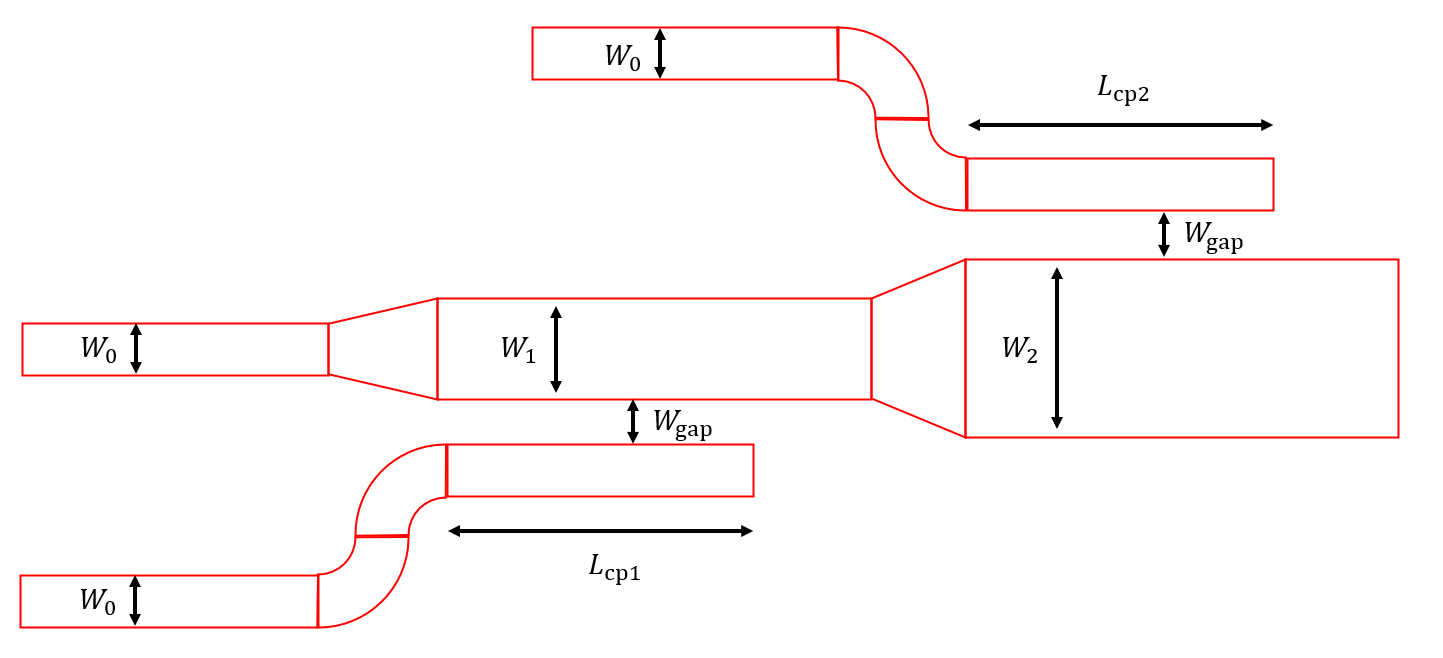

- **Material**: The MUX is fabricated from **Silicon (Si, **$n\approx 3\ldotp 45$@1550nm**)** on a **Silicon Dioxide (SiO2 **$n\approx 1\ldotp 44$@1550nm**)** substrate, with air serving as the upper cladding.

- **Thickness**: The silicon device layer has a thickness of **250 nm**, which is a standard value in integrated photonic fabrication.

- **Coupling gap and length**: The gap between each input waveguide and the multimode bus waveguide is **90 nm**. Two coupling sections are used, each with a length of **20 μm** to ensure efficient power transfer.

- **Waveguide widths**: The bus waveguide widths are designed so that the propagation constants $\beta \;$ (or effective index $n_{\textrm{eff}}$) of the higher-order modes match those of the fundamental modes in the input waveguides. These optimized widths enable selective mode conversion. The corresponding mode orders and effective indices are listed in the table below.

### 1.2 Create MUX device with GDSII file

In this example, the large MUX device is constructed as a `LayerDevice` object. The `LayerDevice` class is designed for planar structures with finite extents along the $z$-direction and offers several practical advantages:

- **Easy geometry definition**: The device geometry is defined on the $x-y$ plane and extended along the $z$-direction, avoiding the need to construct complex 3Dl polygonal models. In addition to analytic shapes, geometries can be imported directly from **GDSII layout files**, enabling a layout-driven workflow that is particularly convenient for industrial users.

- **Fast and memory-efficient meshing**: Compared with full 3D devices, a `LayerDevice` is significantly easier to discretize because meshing is performed on the 2D ($x-y$) plane and then extended along $z$. For large devices, this approach can reduce computational time and memory usage by orders of magnitude relative to full 3D meshing.

- **Natural fit for varFDFD solver**: Devices represented by the `LayerDevice` class naturally satisfy the assumptions of the **varFDFD** formulation, in which the electromagnetic field is approximated using a fixed profile along the collapsed axis ($z$), while scattering and propagation are solved in the transverse ($x-y$) plane. This representation is well suited for structures whose geometry is layer-aligned along $z$ and varies smoothly within the $x-y$ plane.

% substrate: SiO2 sub
modelMUX.addDevice(1);
modelMUX.setDevice(1).setGeometry("Rectangle", 80e-6, 20e-6, 'c', [40e-6, 0]);
modelMUX.setDevice(1).setMaterial(1.44^2); % SiO2
modelMUX.setDevice(1).setEndPoint('zmin', 0, 'zmax', 250e-9); % extrude 2D geometry along z

% core: Silicon MUX
gdspath = fullfile(pwd, './mux_design_Hz.gds');
modelMUX.addDevice(2);
modelMUX.setDevice(2).setGeometry("GDSII", gdspath);


Library name  : mux_design
Creation date : 2025-12-9, 16:50:55
User unit     : 1e-06 m
Database unit : 1e-10 m

Read time  : 00:00:00.000
Structures : 1
Elements   : 3



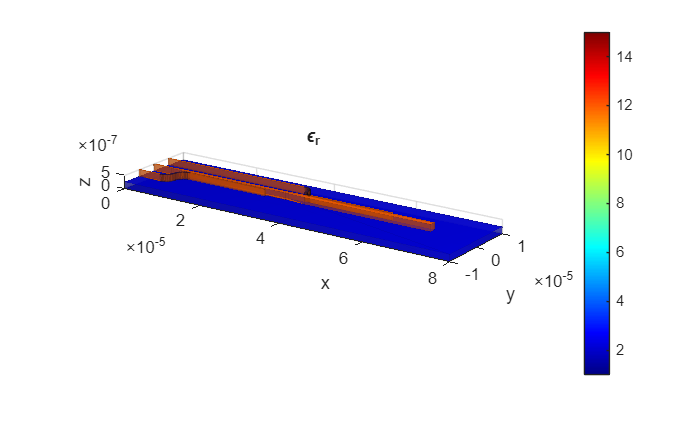

modelMUX.setDevice(2).setMaterial(3.45^2); % Si
modelMUX.setDevice(2).setEndPoint('zmin', 250e-9, 'zmax', 500e-9);

% complete device defination
modelMUX.assembleDevice;
modelMUX.device.dispImg;

## **Step 2: Define mesh grid**

The FDFD solver operates on a uniform Cartesian mesh that discretizes the simulation domain. The mesh is defined by specifying the number of grid points and step sizes along each coordinate axis ($x$, $y$, and $z$). These parameters determine the spatial resolution and range used to represent the device geometry and material distributions.

**Note**: By default, the coordinate axes are centered at **zero**. The `shiftMesh` method of the Modelvar3D class can be used to adjust the coordinate origin or shift the mesh range along a specific direction, if needed. 

% grid size and step length
Nx = 2200;  dx = 30e-9;
Ny = 420;   dy = 30e-9;
Nz = 30;    dz = 25e-9;

% define mesh grid
modelMUX.setMesh([Nx Ny Nz], [dx dy dz]);

% customize coordinate value if needed
modelMUX.shiftMesh("x", "min", 0); % Shift x making it starts at x1=0
modelMUX.shiftMesh("z", "min", 0); % Shift z making it starts at z1=0
[x,y,z] = modelMUX.getCoordinate; % get the simulation coordinate values

% mesh the device after completing the grid definition
modelMUX.meshDevice;

## Step 3: Set up solver

#### 3.1 Set wavelength

This MUX device was designed to work at **1550 nm.**

modelMUX.setWavelength(1.55e-6); % define wavelength for simulation [unit: m]

#### 3.2 varFDFD configuration

Compared with standard FDFD solvers, the varFDFD method requires additional configuration. Based on its variational formulation, a full 3D scattering problem is decomposed into two parts: (i) a 1D eigenmode problem along the collapsed dimension, and (ii) an effective 2D scattering problem in the propagation plane. Therefore, before running the solver, three key parameters must be specified:

- **Collapsed axis**: The spatial dimension to be compressed. In our toolbox, $z$ dimension is fixed as collapsed dimension. 

- **Reference probe location**: To solve the 1D slab eigen problem along the collapsed axis, we must select a reference point $\left(x_r ,y_r \right)$ where the local material profile $\varepsilon_r \left(x=x_r ,y=y_r ,z\right)$ and $\mu_r \left(x=x_r ,y=y_r ,z\right)$is sampled. This reference probe should pass through all layers of the device—cladding (air), core (Si), and substrate (SiO₂)—to approximate the vertical field shape accurately. For the MUX structure, a suitable probe location lies inside the central region of the device. (`"RefPoint", [20e-6,0]`)

- **Polarization**: Although 3D fields do not have strict “transverse modes,” the varFDFD formulation produces an effective 2D scattering problem with a transverse component. Since the MUX is designed using phase matching of its TE-like modes ($E_y$ is dominant in the cross-section), we choose **TM** polarization in varFDFD, which yields the field components $H_z$, $E_x$, and $E_y$. (`"Pol", 'TM'`)

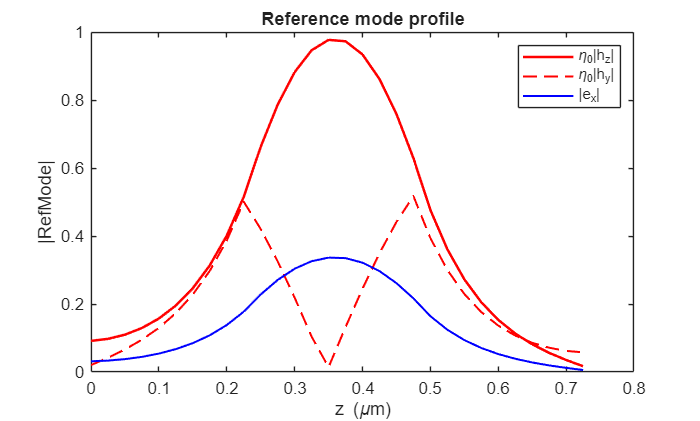

% configure varFDFD solver
modelMUX.setSolver("Pol", 'TM', "RefPoint", [20e-6,0]);

% (check reference mode during varFDFD solving process if needed)
refmode = modelMUX.solution.ref.mode;
figure;
plot(z*1e6, Constant('eta0').v*abs(refmode.Hz), '-r', 'LineWidth', 1.5); hold on;
plot(z*1e6, Constant('eta0').v*abs(refmode.Hy), '--r', 'LineWidth', 1.2); hold on;
plot(z*1e6, abs(refmode.Ex), '-b', 'LineWidth', 1.2); hold off;
xlabel('z (\mum)'), ylabel('|RefMode|');
legend('\eta_0|h_z|', '\eta_0|h_y|', '|e_x|');
title('Reference mode profile')

After solving the reference eigenmode, the effective permittivity $\varepsilon_r^{\textrm{eff}}$ is obtained. This serves as the **2D effective device** that will be used in the subsequent varFDFD scattering simulation.

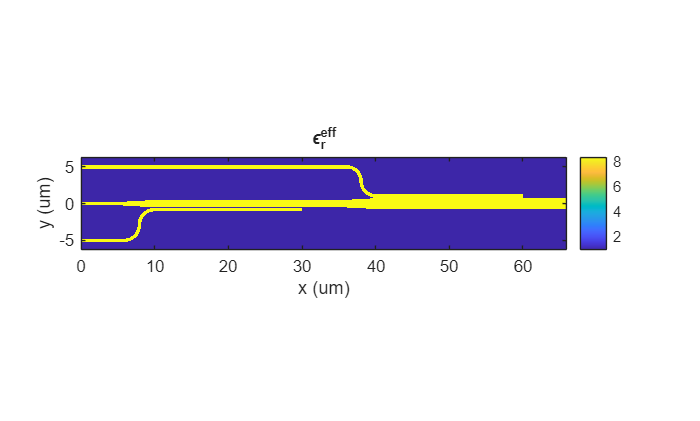

% (check effective index during varFDFD solving process if needed)
eps_eff = modelMUX.solution.epseff;
figure;
imagesc(x*1e6,y*1e6,eps_eff.'); axis image;
xlabel('x (um)'); ylabel('y (um)'); set(gca,'YDir','normal');
colorbar;
title('\epsilon_r^{eff}');

#### 3.3 Boundary condition

We need to set the boundary conditions for the 2D effective problem before running solver. **Perfectly Matched Layers (PML)** are applied along the $x-$ and $y-$directions to suppress reflections from the computational window. In most cases, a PML thickness of about 8~15 pixels is sufficient. Since the $z$-dimension has been collapsed in the varFDFD formulation, no boundary conditions are required along that axis.

**Note**: **PML** is the **default** boundary condition for all scattering solvers, with a default thickness of **8 layers**.

modelMUX.setBoundary("x", "PML", 15); % 15 layers at both sides at x dimension
modelMUX.setBoundary("y", "PML", 15); % 15 layers at both sides at y dimension

## Step 3: Port and source

Place a port over one of the three input branches of the MUX. The fundamental eigenmode of the selected input waveguide is used as the excitation, launched toward the $+x$ direction. There is no need to explicitly specify the eigenmode polarization—the source automatically inherits the polarization specified in the varFDFD solver's configuration.

**Note**: The varFDFD solver only accepts **port eigenmodes** as input sources. Plane-wave or Gaussian-beam excitations are not supported because they violate a fundamental assumption of the variational formulation: the field’s profile in the $z$-dimension is assumed to be the fundamental guided slab mode and remains unchanged during propagation.

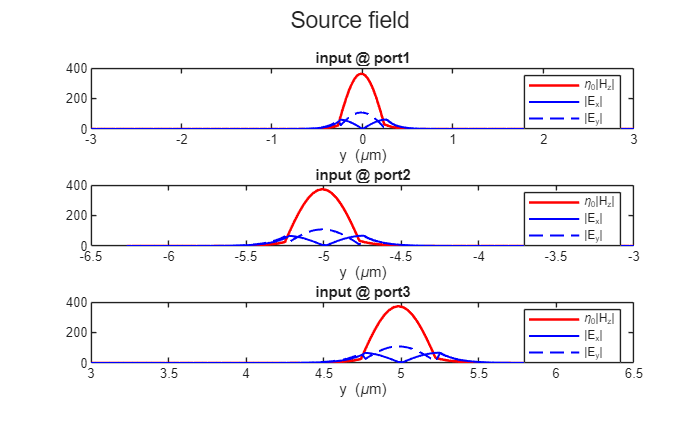

% port y-span
port_y_span = [-3e-6, 3e-6;... % input port 1 -> fundamental mode output
                -8e-6, -3e-6; ...  % input port 2 -> 2nd TE mode output
                3e-6 8e-6];  % input port 3 -> 3rd TE mode output

for ii = 1:3
    % define source port
    modelMUX.addPort('+x', 3e-6, port_y_span(ii, :));

    % choose fundamental eigenmode as source
    modelMUX.addSource(1); % input desired mode number of eigenmodes

    % display eigenmode source field
    eigen_src = modelMUX.getSource;
    port_src_y = eigen_src.mesh.v;

    figure(100); sgtitle('Source field')
    subplot(3,1,ii);
    plot(port_src_y*1e6, Constant('eta0').v*abs(eigen_src.Hz), '-r', 'LineWidth', 1.5); hold on;
    plot(port_src_y*1e6, abs(eigen_src.Ex), '-b', 'LineWidth', 1.2); hold on;
    plot(port_src_y*1e6, abs(eigen_src.Ey), '--b', 'LineWidth', 1.2); hold off;
    xlabel('y (\mum)');
    legend('\eta_0|H_z|', '|E_x|', '|E_y|');
    title(['input @ port', num2str(ii)]);

## Step 4: Solve varFDFD

After all configurations are complete, we invoke the `solveModel` method of the `Model3D` object to run the varFDFD simulation. Once the computation finishes, the field components can be retrieved using `exportResult`.

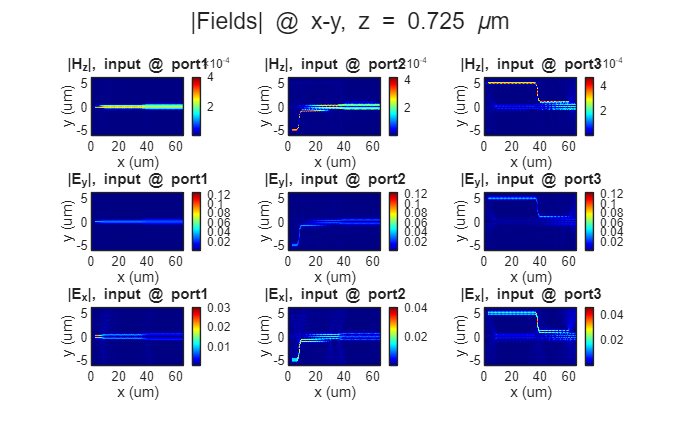

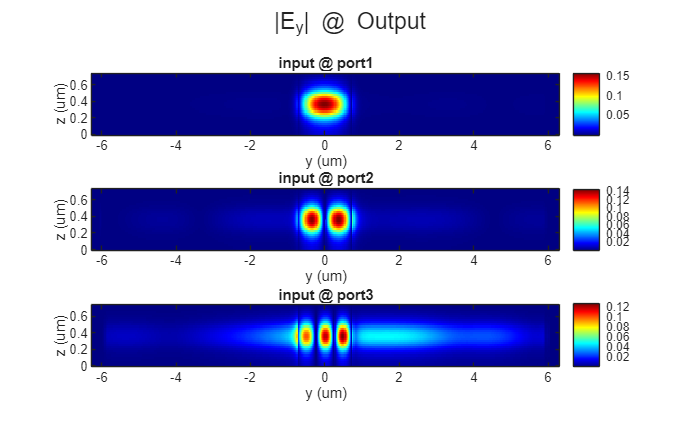

    % solve the model
    modelMUX.solveModel;
    varsol = modelMUX.exportResults;

    % display scattering field results
    Hz = varsol.Hz;
    Ex = varsol.Ex;
    Ey = varsol.Ey;
    [~, z_slice] = min(abs(z-375e-5)); % select z-slice at the core layer
    [~, x_slice] = min(abs(x-63.5e-6)); % select x-slice at the output port

    figure(200); sgtitle(['|Fields| @ x-y, z = ', num2str(z(z_slice)*1e6),' \mum'])
    subplot(3,3,ii);
    imagesc(x*1e6,y*1e6,squeeze(abs(Hz(:,:,25))).');
    xlabel('x (um)'); ylabel('y (um)'); set(gca,'YDir','normal');
    colormap jet; colorbar;
    title(['|H_z|, input @ port', num2str(ii)]);
    subplot(3,3,3+ii);
    imagesc(x*1e6,y*1e6,squeeze(abs(Ey(:,:,25))).');
    xlabel('x (um)'); ylabel('y (um)'); set(gca,'YDir','normal');
    colormap jet; colorbar;
    title(['|E_y|, input @ port', num2str(ii)]);
    subplot(3,3, 6+ii);
    imagesc(x*1e6,y*1e6,squeeze(abs(Ex(:,:,25))).');
    xlabel('x (um)'); ylabel('y (um)'); set(gca,'YDir','normal');
    colormap jet; colorbar;
    title(['|E_x|, input @ port', num2str(ii)]);

    figure(300); sgtitle('|E_y| @ Output');
    subplot(3,1,ii);
    imagesc(y*1e6,z*1e6,squeeze(abs(Ey(x_slice,:,:))).');
    xlabel('y (um)'); ylabel('z (um)'); set(gca,'YDir','normal');
    colormap jet; colorbar;
    title(['input @ port', num2str(ii)]);
end

$E_y$ field at the output port is successfully converted into the desired spatial mode, depending on which input port is excited.